clearvars
close all
clc

# Model Based Regulator Design of Cart Pole System

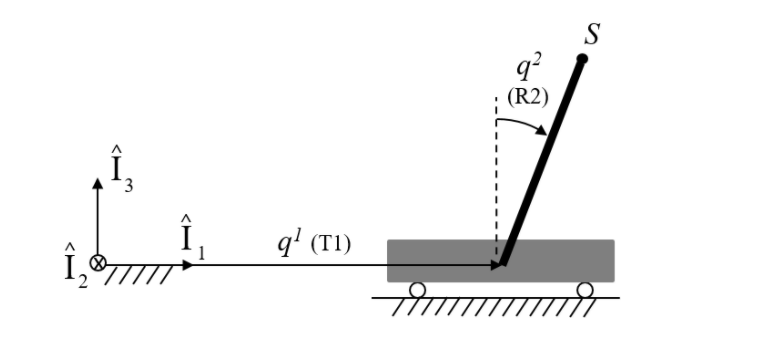

## System Description

The cart translates with respect to the inertial frame in one dimension freely and no external force is applied on the cart. The cart is assumed to be a simple lumped mass block. The pole is a uniformly distributed stick with its centre of mass at its geometric centre. It rotates with respect to the translating cart with the help of a revolute joint. The system is a lumped parameter system which can be represented by ordinary differential equations.

## System Parameters:

#### 
$$m_{Cart} = 10 kg$$


#### 
$$m_{Pole} = 2 kg$$


#### 
$$l_{Pole} = 4 m$$


% Cart mass
M = 10;%kg

% Pole mass
m = 2;%kg

% Pole length
L = 4;%meters

% Acceleration due to gravity
g = 9.81; %m/s^2

% Time Step Size
dt = 0.01;

% Time Vector
t_span = [0:dt:10];


### State vector of system:

### 
$$\;\mathbf{w}=\;\left\lbrack \begin{array}{c}
x\\
\theta \\
\dot{x} \\
\theta^˙ 
\end{array}\right\rbrack$$


### First Derivative of states:

### 
$$\dot{\mathbf{w}} =\left\lbrack \begin{array}{c}
\dot{x} \\
\theta^˙ \\
\ddot{x} \\
\theta^¨ 
\end{array}\right\rbrack$$


### Initial conditions of the system:

The cart is assumed to be at 0.1 m to the right (positive X axis) initially, with all the other states at zero.

w_0 = [0;0.5;0;0]; 

# Dynamics of Actuated Cart Pole System:

#### Euler-Lagrange Equation of the system:

### $\frac{d}{dt}\left(\frac{\partial L}{\partial \dot{q}}\right) - \frac{\partial L}{\partial q} = Q(t)$, for an actuated/forced system

## Linear State space representation of the system:

The equations of motion of the cart pendulum system can be written as:

## Case 1: Actuation provided to Cart and Pole Joint

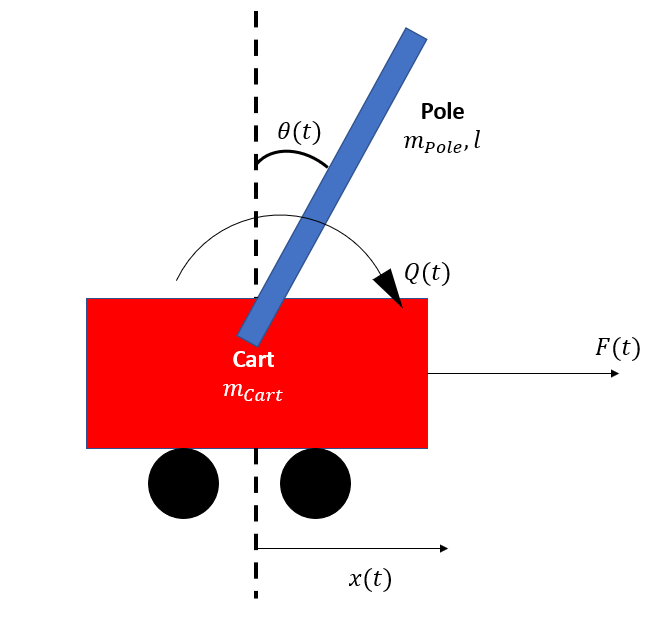

#### Linearized Equation of Motion (assuming small pole joint rotations):

### 
$$(m_{Cart} + m_{Pole})\ddot{x}_{Cart} + \frac{m_{Pole}l_{Pole}}{2}\ddot{\theta} = f(t)$$


### 
$$\frac{m_{Pole}l_{Pole}^{2}}{3}\ddot{\theta} + \frac{m_{Pole}l_{Pole}}{2}\ddot{x}_{Cart} - \frac{m_{Pole}gl_{Pole}}{2}\theta = Q(t)$$


### 
$$\dot{\textbf{w}} = \textbf{A}\cdot\textbf{w} + \textbf{B}\cdot\textbf{u}$$


### where,

### $\mathbf{A}=\left\lbrack \begin{array}{cc}
\mathbf{O} & \mathbf{I}\\
{-\mathbf{M}}^{-1} \mathbf{K} & \mathbf{O}
\end{array}\right\rbrack$, system matrix / State Weighing Matrix

### $\mathbf{B}=\left\lbrack \begin{array}{c}
\mathbf{O}\\
{\mathbf{M}}^{-1} 
\end{array}\right\rbrack$, Control Cost Matrix

### $\mathbf{M}=\left\lbrack \begin{array}{cc}
m_{\mathit{Cart}} +m_{\mathit{Pole}}  & \frac{m_{\mathit{Pole}} l_{\mathit{Pole}} }{2}\\
\frac{m_{\mathit{Pole}} l_{\mathit{Pole}} }{2} & \frac{m_{\mathit{Pole}} {l_{\mathit{Pole}} }^2 }{3}
\end{array}\right\rbrack$, **mass matrix**

### $\mathbf{K}=\left\lbrack \begin{array}{cc}
0 & 0\\
0 & -\frac{m_{\mathit{Pole}} gl_{\mathit{Pole}} }{2}
\end{array}\right\rbrack$, **stiffness matrix**

% Mass Matrix
M_mat = [m + M,(m*L)/2;
    (m*L)/2,(m*(L)^2)/3];
% Stiffness Matrix
K_mat = [0,0;
    0,(-m*g*L)/2];
% State Weighing matrix
A = [zeros(2,2),eye(2,2);-M_mat\K_mat,zeros(2,2)];
% Controller Cost matrix
B = [zeros(size(M_mat)) ; M_mat\eye(size(M_mat))];

## **Controller Gains**

% Controller Gain Matrix
Kc = [100,100;
     100,100];
% % Proportional Gain Matrix
% Kp = [5,1;
%     1,2];
% % Derivative Gain Matrix
% Kd = [2,1;
%     1,2];

## Response of the Closed Loop Model Based Control System:

[t,w] = ode45(@(t,w)ModelBasedControl_SSR(t,w,M_mat,K_mat,Kc,A,B),t_span,w_0);

% Closed Loop System Weighing Matrix
A_cl = A + [B*(K_mat - M_mat*Kc), zeros(4,2)];
% A_cl = A + [B*(K_mat - M_mat*Kp), -B*M_mat*Kd];
% Closed Loop Eigen-values
eig(A_cl)

ans =   -0.0000 +14.1421i
  -0.0000 -14.1421i
  -0.0000 + 0.0000i
   0.0000 + 0.0000i


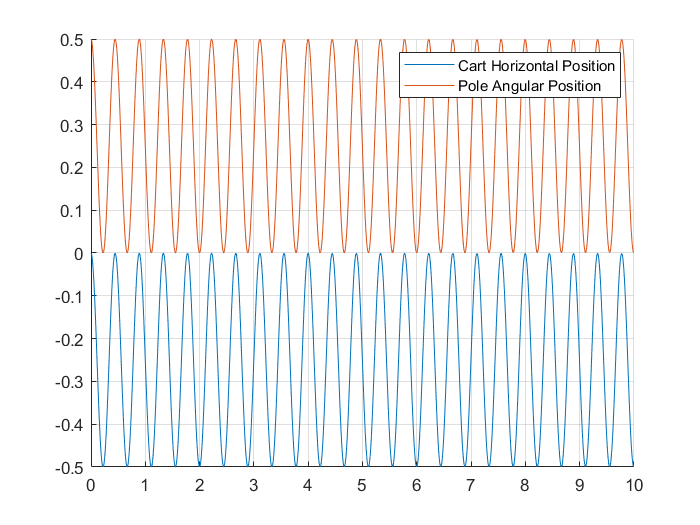


% Response of the Closed Loop Control System
figure
hold on
plot(t_span,w(:,1))
plot(t_span,w(:,2))
legend('Cart Horizontal Position','Pole Angular Position')
grid on

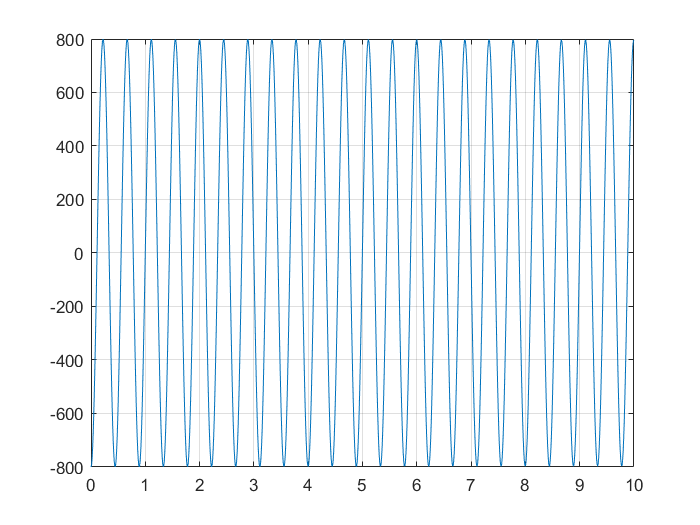


% Controller/Actuator Effort
for i = 1:max(size(w))
    u(:,i) = -M_mat*Kc*[w(i,1);w(i,2)] + K_mat*[w(i,1);w(i,2)];
%     u(:,i) = -M_mat*Kd*[w(i,3);w(i,4)] + (K_mat - M_mat*Kp)*[w(i,1);w(i,2)];
    uCart(i) = u(1,i);
    uPole(i) = u(2,i);
end

figure
plot(t_span,uCart)
grid on

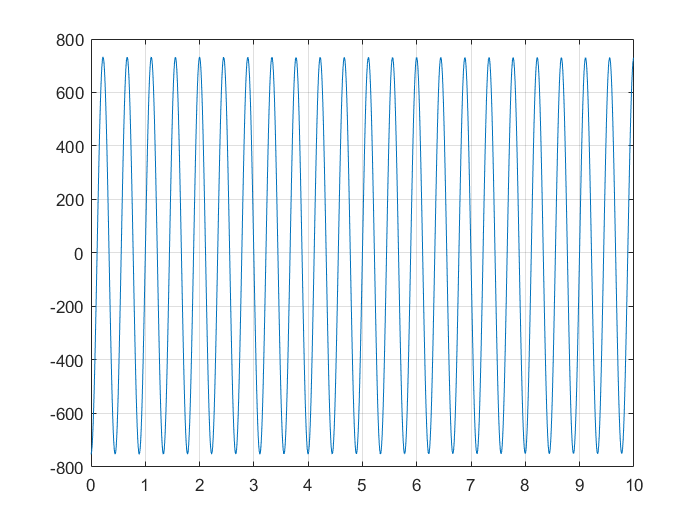


figure
plot(t_span,uPole)
grid on